# Progetto Controlli Automatici

## Esperimenti Equilibrio

clc
clear
close all

addpath(genpath("..\"));

set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');

load("modello\data.mat");
warning("off" , "all");
load_system("modello\model.mdl");

N = length(time);
Ts = time(2) - time(1);

colori = lines(2);

Simulazione con i segnali dati:

sim("model");

i = 1

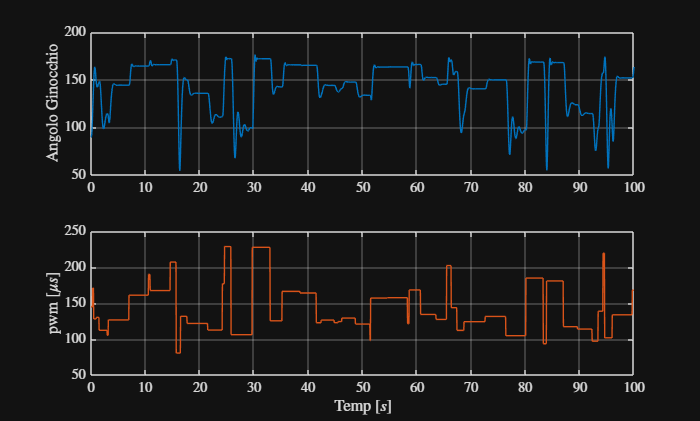

figure;
subplot(2 , 1 ,1);
plot(time , y , Color=colori(1 , :));
ylabel("Angolo Ginocchio")
grid on;
subplot(2 , 1 , 2);
plot(time , u , Color=colori(2 , :));
ylabel("pwm $[\mu s]$");
xlabel("Temp $[s]$");
grid on;

#### Test di diverse intensita:

pw = [zeros(201,1); 25 * ones(200 , 1) ; 50 * ones(200 , 1);
75* ones(200 , 1);100 * ones(200 , 1); linspace(100 , 120 , 200)';
120*ones(800 , 1)];
sim("model");

i = 1

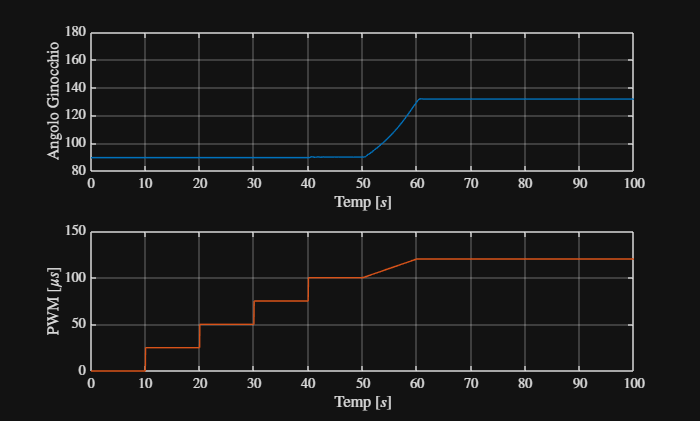

figure
subplot(2 , 1 , 1);
plot(time , y , DisplayName="Angolo Ginocchio" , Color=colori(1 , :));
ylim([80 180]);
ylabel("Angolo Ginocchio");
xlabel("Temp $[s]$");
grid on

subplot(2 , 1 , 2);
plot(time , u , DisplayName="PWM" , Color=colori(2 , :));
ylim([0 150]);
ylabel("PWM $[\mu s]$");
xlabel("Temp $[s]$");
grid on

## Si sceglie un punto di equliblio a $135\degree $

Risposta allo scalino:

pw_eq = 121.35;

pw = [zeros(10/Ts , 1) ;            % 10 secondi a 0
        pw_eq * ones(20/Ts , 1);    % 20 secondi a 116.5
        zeros(70/Ts +1 , 1)];
sim("model");

i = 1

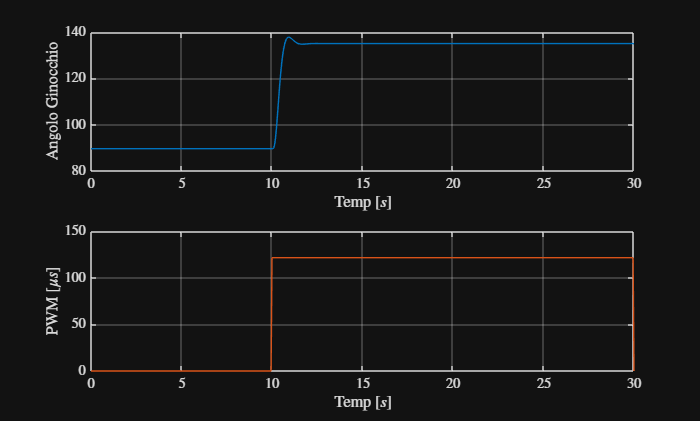

figure
subplot(2 , 1 , 1);
plot(time , y , DisplayName="Angolo Ginocchio" , Color=colori(1 , :));
ylabel("Angolo Ginocchio");
xlabel("Temp $[s]$");
xlim([0 30])
grid on

subplot(2 , 1 , 2);
plot(time , u , DisplayName="PWM" , Color=colori(2 , :));
ylabel("PWM $[\mu s]$");
xlabel("Temp $[s]$");
xlim([0 30])
grid on

#### Osservazione del ritardo puro d'ingresso

Si trovano circa $5 /10\mu s$ di ritardo che corrsipondono a $1/2 $passi di simulazione:

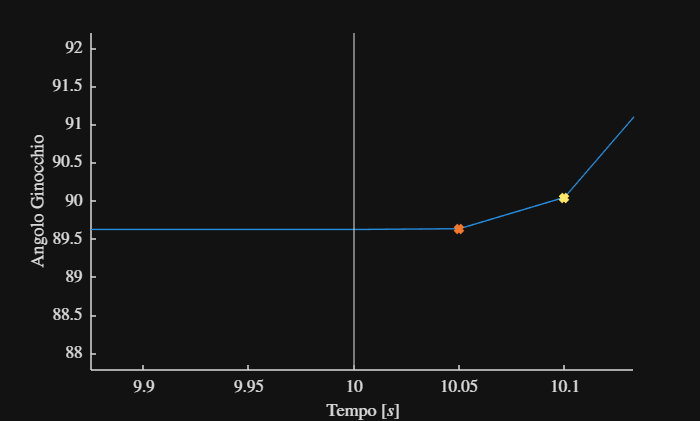

figure;
indice_inizio = floor(9.95/Ts);
indice_fine = floor(10.5/Ts);
intervallo = indice_inizio:indice_fine;
y_zoom = y(intervallo);
passo_1 = 202;
passo_2 = 203;
time_zoom = time(intervallo);
hold on
plot(time_zoom , y_zoom);
plot(time(passo_1) , y(passo_1) , Marker="x" , LineWidth=3);
plot(time(passo_2) , y(passo_2) , Marker="x" , LineWidth=3);
xline(10)
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
hold off;

xlim([9.875 10.133])
ylim([87.78 92.21])
 
hDataTip = findobj(gca,"DataIndex",1);
set(hDataTip,"Location","northwest");
ax2 = gca;
chart = ax2.Children(2);
datatip(chart,10.1,89.95,"Location","southeast");
chart = ax2.Children(4);
datatip(chart,10,89.62,"Location","southwest");
datatip(chart,9.9,89.62,"Location","northeast");
chart = ax2.Children(3);
datatip(chart,10.05,89.63,"Location","southeast");

# **Identificazione**

Si vuole controllare l'angolo nell'introno $\pm 10\degree $ rispetto all'equilibrio ($145\degree $, $125\degree $) si è scelto di creare 3 segnali diversi per l'input:

- Randomico a blocchi costanti di $5s$con valori compresi tra $117\ldotp 5\mu$ e $127.1 \mu$;

- PRBS con ampiezza $117\ldotp 5\mu$ e $127.1 \mu$;  

- Vaolori randomici tra $117\ldotp 5\mu$ e $127.1 \mu$ a blocchi con tempi variabili tra $0\ldotp 5s$ e $5s$.

pw_max = 127.1;
pw_min = 117.5;

% i primi tre secondi
primi_secondi = 3/0.05;
time_ridotto = time(primi_secondi:end);


### Randomico a blocchi costanti di $5s\;\;$con valori compresi tra $117\ldotp 5\mu$ e $127.1 \mu$

load("pw_1.mat");

pw = pw_1;
sim("model");

i = 1

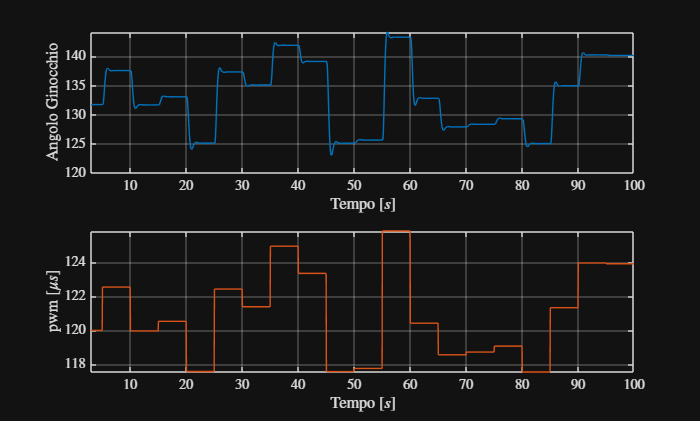

y_1 = y(primi_secondi:end);
pw_1 = pw_1(primi_secondi:end);
figure;
subplot(2 , 1 , 1);
plot(time_ridotto , y_1 , Color = colori(1 ,:));
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
xlim([3 100])
grid on;
subplot(2 , 1 , 2);
plot(time_ridotto , pw_1, Color = colori(2 ,:));
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")
xlim([3 100])
grid on

### PRBS con ampiezza $117\ldotp 5\mu$ e $127.1 \mu$


pw_2 = idinput(N , 'prbs' , [0 0.7] , [pw_min , pw_max]);
pw = pw_2;

sim("model");

i = 1

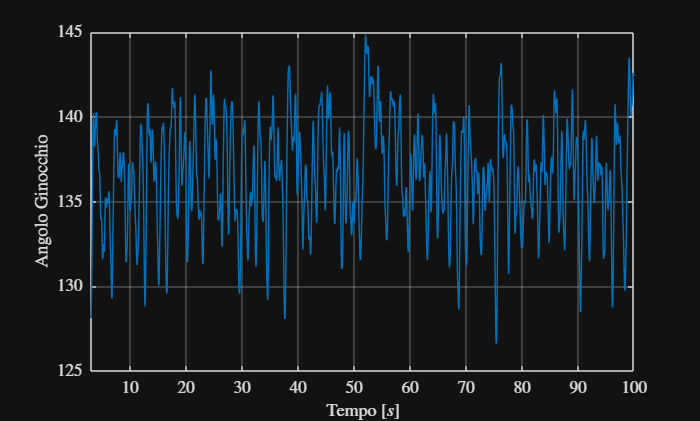

y_2 = y(primi_secondi:end);
pw_2 = u(primi_secondi:end);
figure;
subplot(1 , 1 , 1);
plot(time_ridotto , y_2, Color = colori(1 ,:));
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
xlim([3 100])
grid on;

% subplot(2 , 1 , 2);
% plot(time_ridotto , pw_2, Color = colori(2 ,:));
% ylabel("pwm $[\mu s]$")
% xlabel("Tempo $[s]$")
% xlim([3 100])
% grid on

### Vaolori randomici tra $117\ldotp 5\mu$ e $127.1 \mu$ a blocchi con tempi variabili tra $0\ldotp 5s$ e $5s$

load("pw_3.mat");
pw = pw_3;
sim("model");

i = 1

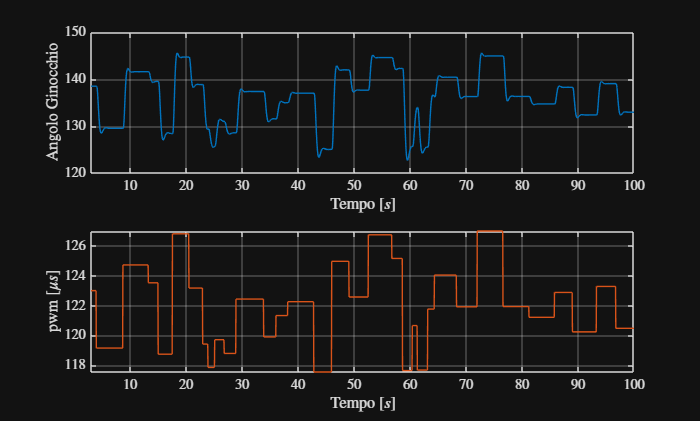

y_3 = y(primi_secondi:end);
pw_3 = u(primi_secondi:end);
figure;
subplot(2 , 1 , 1);
plot(time_ridotto , y_3 , Color=colori(1 , :));
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
xlim([3 100])
grid on;
subplot(2 , 1 , 2);
plot(time_ridotto , pw_3 , Color=colori(2 , :));
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")
xlim([3 100])
grid on

## Identificazione del Modello

### Si utilizza il segnale randomico a blocchi costanti di $5s$

% Divisione del data set 70% e 30%
N = length(y_1);

n_70 = floor(N*0.7);
y_modello = y_1(1:n_70);
u_modello = pw_1(1:n_70);

data_ident = iddata(y_modello , u_modello , Ts);

% Validazione con il 30% del primo set
n_30 = N - n_70;

y_val = y_1(1:n_30);
u_val = pw_1(1:n_30);

data_val = iddata(y_val , u_val , Ts);

%definizione ordini AR MA X e K
n_ar = 5;
n_x = 3;
n_ma = 1;
k = 2;

%Sima del modello
modello_armax_1 = armax(data_ident , [n_ar n_x n_ma k])


modello_armax_1 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                   
  A(z) = 1 - 3.424 z^-1 + 4.618 z^-2 - 3.099 z^-3 + 1.067 z^-4 - 0.1611 z^-5
                                                                            
  B(z) = 0.02211 z^-2 + 0.0105 z^-3 - 0.03264 z^-4                          
                                                                            
  C(z) = 1 + 0.7382 z^-1                                                    
                                                                            
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=3   nc=1   nk=2
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "data_ident".
Fit to estimation data: 99.98% (prediction focus)      
FPE: 1.027e-06, MSE: 1.006e-06                         
 
<a hr

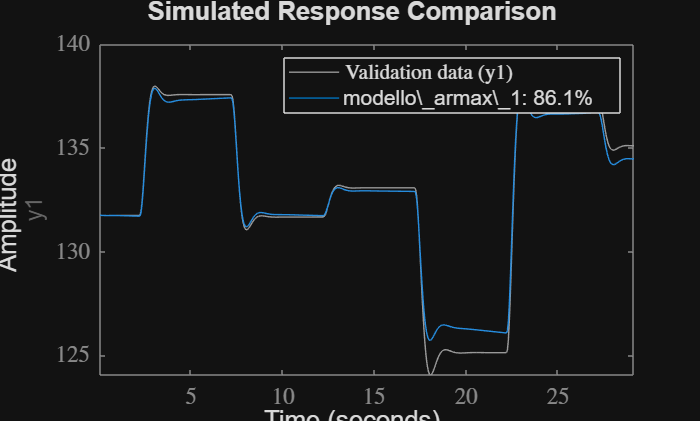

figure
compare(data_val, modello_armax_1);

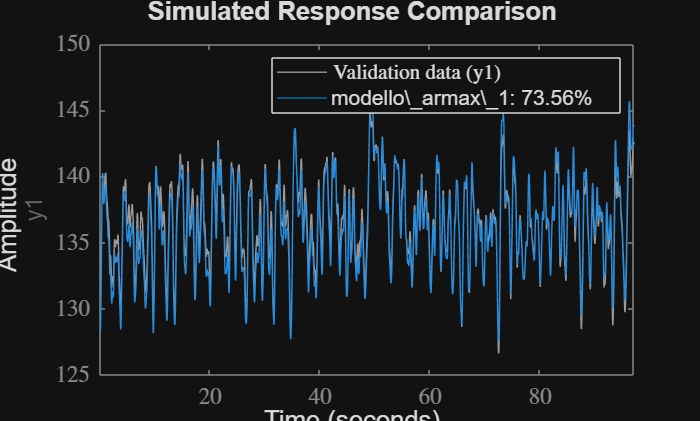

% Validazione con gli altri set
y_val = y_2;
u_val = pw_2;

data_val = iddata(y_val , u_val , Ts);
figure

compare(data_val, modello_armax_1);

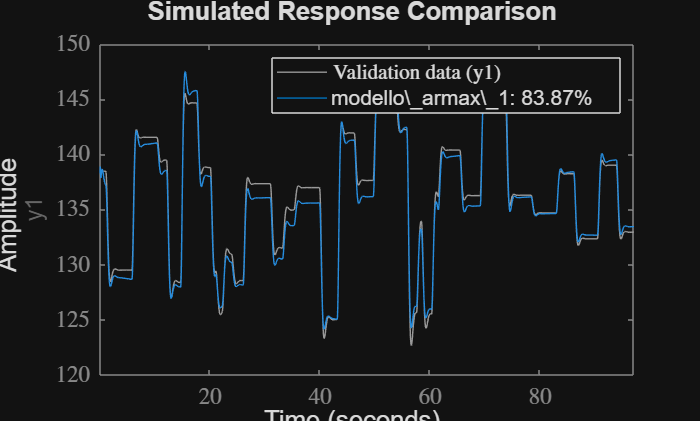

y_val = y_3;
u_val = pw_3;

data_val = iddata(y_val , u_val , Ts);

compare(data_val, modello_armax_1)

## Si utilizza il segnale PRBS

% 70% dei dati
y_modello = y_2(1:n_70);
u_modello = pw_2(1:n_70);

data_ident = iddata(y_modello , u_modello , Ts);

% Validazione con il 30% del secondo set
n_30 = N - n_70;

y_val = y_2(1:n_30);
u_val = pw_2(1:n_30);

data_val = iddata(y_val , u_val , Ts);

%definizione ordini AR MA X e K
% n_ar = 5;
% n_x = 3;
% n_ma = 1;
% k = 2;

%Stima del modello
modello_armax_2 = armax(data_ident , [n_ar n_x n_ma k])


modello_armax_2 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                    
  A(z) = 1 - 3.394 z^-1 + 4.522 z^-2 - 2.981 z^-3 + 0.9973 z^-4 - 0.1448 z^-5
                                                                             
  B(z) = 0.02191 z^-2 + 0.01061 z^-3 - 0.03255 z^-4                          
                                                                             
  C(z) = 1 - 0.6302 z^-1                                                     
                                                                             
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=3   nc=1   nk=2
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "data_ident".
Fit to estimation data: 99.51% (prediction focus)      
FPE: 0.0002485, MSE: 0.0002434                         


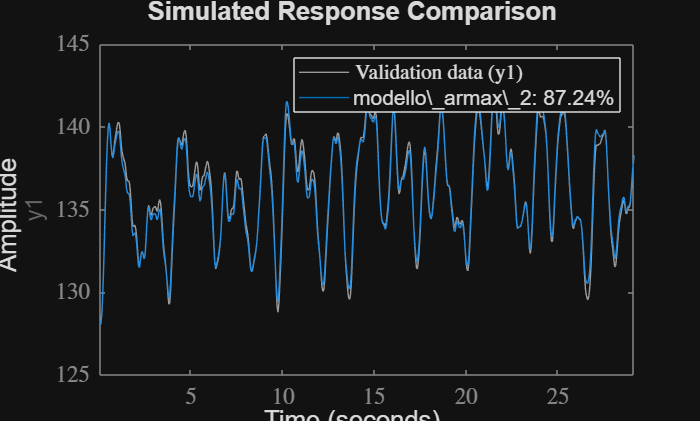

figure
compare(data_val, modello_armax_2);

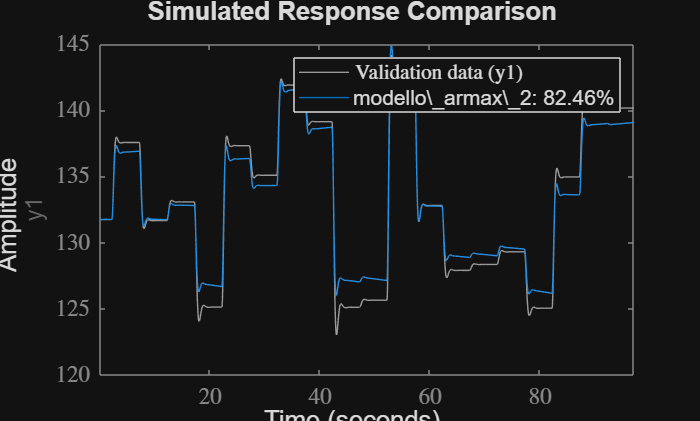


% Validazione con gli altri set
y_val = y_1;
u_val = pw_1;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax_2)

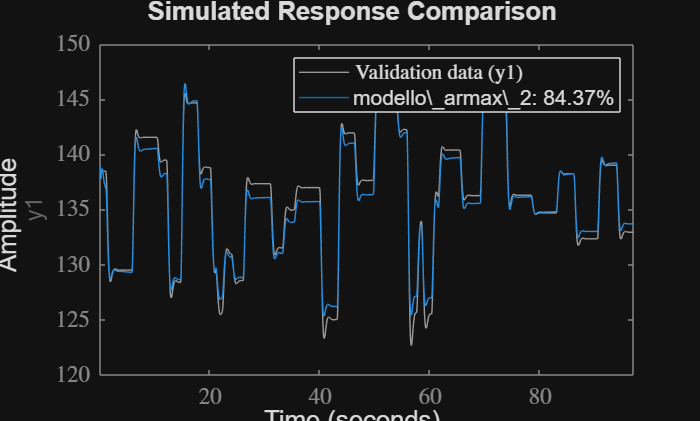

% Validazione con il terzo set
y_val = y_3;
u_val = pw_3;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax_2)

## Si utilizza il segnale randomico a blocchi variabili

% 70% dei dati
n_70 = floor(N*0.7);
y_modello = y_3(1:n_70);
u_modello = pw_3(1:n_70);


data_ident = iddata(y_modello , u_modello , Ts);

% Validazione con il 30%
n_30 = N - n_70;

y_val = y_3(1:n_30);
u_val = pw_3(1:n_30);

data_val = iddata(y_val , u_val , Ts);

%definizione ordini AR MA X e K
% n_ar = 5;
% n_ma = 1;
% n_x = 3;
% k = 2;

%Sima del modello
modello_armax_3 = armax(data_ident , [n_ar n_x n_ma k])


modello_armax_3 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                   
  A(z) = 1 - 3.418 z^-1 + 4.593 z^-2 - 3.062 z^-3 + 1.041 z^-4 - 0.1544 z^-5
                                                                            
  B(z) = 0.02229 z^-2 + 0.01027 z^-3 - 0.03262 z^-4                         
                                                                            
  C(z) = 1 + 0.6204 z^-1                                                    
                                                                            
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=3   nc=1   nk=2
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "data_ident".
Fit to estimation data: 99.97% (prediction focus)      
FPE: 2.717e-06, MSE: 2.661e-06                         
 
<a hr

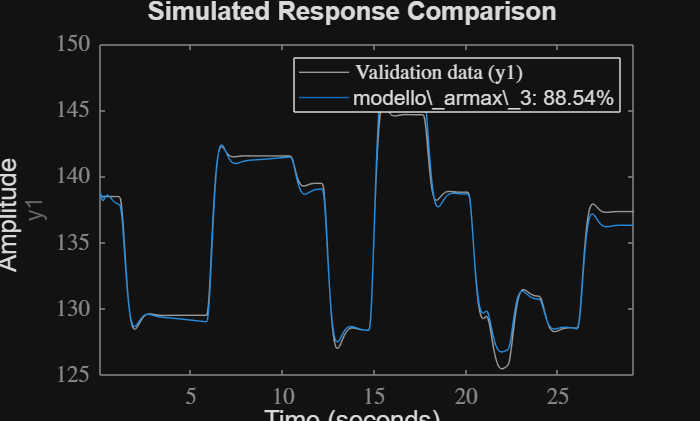



figure
compare(data_val, modello_armax_3)

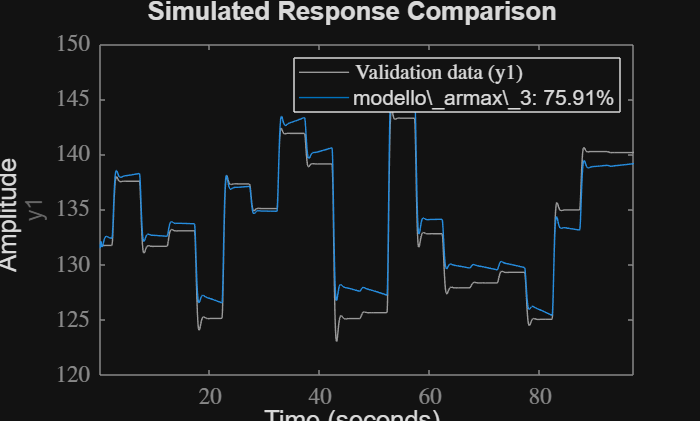


% Validazione con il primo set
y_val = y_1;
u_val = pw_1;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax_3)

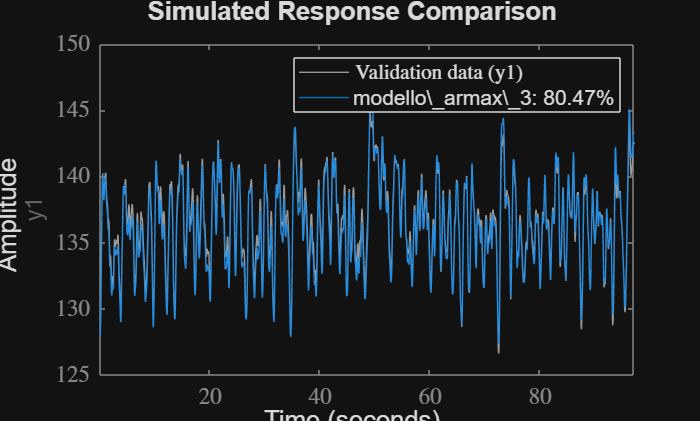

% Validazione con il secondo set
y_val = y_2;
u_val = pw_2;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax_3)